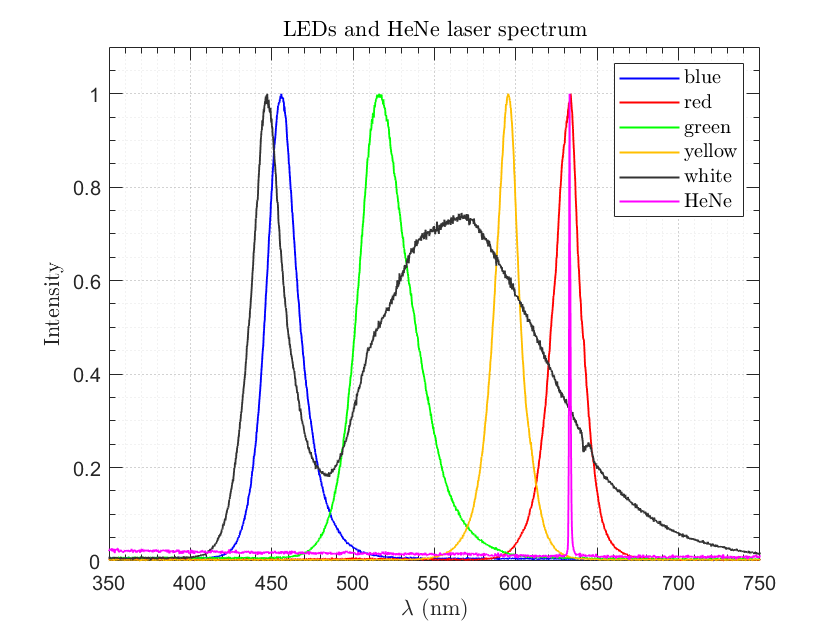

% ================= Blue LED ================= %
d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\BLED.txt");
lambda = d(:,1);
Ia = d(:,2);
Ia = normalize_intensity(Ia);
plot(lambda,Ia, "Color", [0 0 1], "DisplayName", "blue", 'LineWidth', 0.95)
title('LEDs and HeNe laser spectrum', "Interpreter", "latex"); 
xlabel('$\lambda$', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid
xlim([200 700])
hold on
% ================= Red LED ================= %

d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\RLED.txt");
Ib = d(:,2);
Ib = normalize_intensity(Ib);
plot(lambda,Ib, "Color", [1 0 0], "DisplayName", "red", 'LineWidth', 0.95)
xlabel('$\lambda$', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
xlim([400 800])

% ================= Green LED ================= %

d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\GLED.txt");
Ic = d(:,2);
Ic = normalize_intensity(Ic);
plot(lambda,Ic, "Color", [0 1 0], "DisplayName", "green", 'LineWidth', 0.95)
xlabel('$\lambda$', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
xlim([300 800])

% ================= Yellow LED ================= %

d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\YLED.txt");
Id = d(:,2);
Id = normalize_intensity(Id);
plot(lambda,Id, "Color", "#FFBF00", "DisplayName", "yellow", 'LineWidth', 0.95)
xlabel('$\lambda$', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
xlim([300 900])

% ================= White LED ================= %

d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\WLED.txt");
Ie = d(:,2);
Ie = normalize_intensity(Ie);
plot(lambda,Ie, "Color", [0.2 0.2 0.2], "DisplayName", "white", 'LineWidth', 0.95)
xlabel('$\lambda$', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);


% ================= HeNE Laser ================= %

d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\RLASER.txt");
If = d(:,2);
If = normalize_intensity(If);
plot(lambda,If, "Color", "magenta", "DisplayName", "HeNe", 'LineWidth', 0.95)
xlabel('$\lambda$ (nm)', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
xlim([350 750])
ylim([0 1.1])


legend('Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 10)

hold off

f = gcf();
exportgraphics(f, 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\SpectrumComp.pdf')

function norm_I = normalize_intensity(I)

    norm_I = (I - min(I))./(max(I)-min(I));

end
